% 

## 1.  Equal cluster size and unequal cluster size			

### ﻿Corollary II.2 (Separation upper bound, equal cluster size)

### 
$$\bar{\Delta}^2_{eq}
=
4 \sigma^2
\left(
1+\sqrt{1+\frac{Kp}{n \log n}}
\right)\log n$$


- for $\alpha >0

$,	

- if the number of clusters is small enough i.e. $K 
\leq
C_1(\alpha) \frac{\log n }{\log \log n}$,

Then if the separation is larger than $(1+\alpha) \bar{\Delta}^2_{eq}$, SDP-relaxed K-means  achieves exact recovery with high probability.				

### Theorem II.1 (Separation Upper Bound, unequal cluster size) 


$$\bar{\Delta}^2_{uneq}
=
4 \sigma^2
\left(
1 + \sqrt{
1 + \frac{(1-\beta)^2}{(1+\delta)}
\frac{p}{m \log n}
+ C_3 R_n
}
\right)
\log n$$


- for $\beta \in (0,1)$ and $\delta >0
$,

- if the number of clusters is small enough i.e. $K \leq C_2 \frac{\beta^2}{ \delta(1-\beta)^2}$

- restrictions on $m, \beta, \delta$

- a quantity $R_n
$ depends on $n, \beta, \delta, p
$

Then if the separation is larger than $\frac{1+ 2\delta}{(1-\beta)^2} \bar{\Delta}^2_{uneq}$	, SDP-relaxed K-means  achieves exact recovery with high probability.

$\delta 
$ here is similar to $\alpha$ in equal cluster size case, but corrected by $1/(1-\beta)^2 \in (1, \infty)$		

## 2. behavior of the separation upper bound

n=200, sigma = 1


$$\bar{\Delta}^2_{eq}
=
4 \sigma^2
\left(
1+\sqrt{1+\frac{Kp}{n \log n}}
\right)\log n
$$


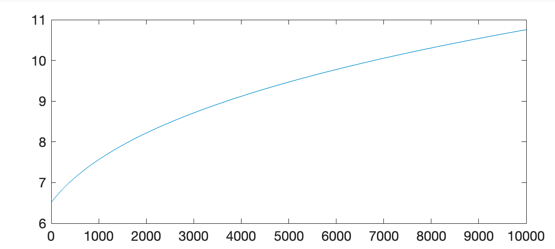

minimum separation roughly ranges from **6 to 11**

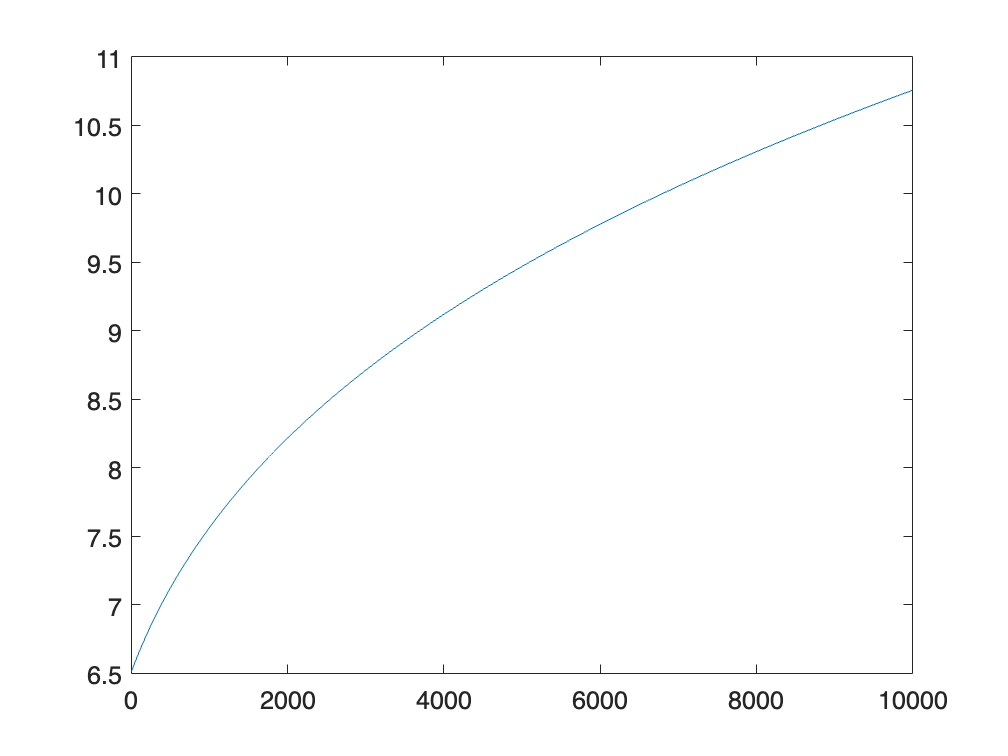

sep_upper_bd = @(p, n, sigma) sqrt( log(n)*4 * sigma^2* ( 1 + sqrt( 1 + 2*p/n/log(n) ) ) );
sep_upper_bd_for_p =  @(p) (sep_upper_bd(p, 200, 1));
p_linspace = linspace(1,10000, 10000);
sep_upper_bd_linspace = sep_upper_bd_for_p(p_linspace);
figure;
plot(p_linspace, sep_upper_bd_linspace)

## 3. Strategy

From Professor Chen's slide, it seems that the error rate is high in p=6000, so **fix p at 6000. **Fix sigma=1 and K=2

- With **s=p (full entry)**, observe **clustering accuracy **= percentage of right cluster prediction (from 200 samples), averaged over 20 iteration, with **separation = [1, 2, ..., 10] **-> failure happens between 6 and 7

- Narrowing down, with **s=p (full entry)**, observe **clustering accuracy **= percentage of right cluster prediction (from 200 samples), averaged over 20 iteration, with **separation = [6.0, 6.1, 6.2, ..., 7] **-> failure happens around 6.6

- Fix separation at 6.6, fix p=6000. **try s = [5000, 4000, 3000, 2000, 1000, 500, 100, 10]. **If Professor Chen's algorithm does not adapt to sparsity, the algorithm will fail for any s.

Note: unlike p=1, for given separation $\Delta
$, we need to set each non-zero entry as  $M
$or$-M$, where


$$\Delta^2 = \|\mu_1 - \mu_2\|_2^2 = \sum_{i=1}^s (2M)^2 = 4sM^2$$


## Step 1: p=6000, s=6000, separation 1 to 10

sigma=1;
rounding = 1e-4;
cluster_true = [repelem(1,n/2), repelem(2,n/2)];

p = 6000;
s = p;
n_rep = 20;
sep_vec = [10, 9, 8, 7, 6, 5, 4, 3, 2, 1]; %round 1

mean_full =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


%sep_vec = linspace(7, 6, 10); %round 2;
mean_full = [ones(p, 1)]';


clustering_acc = repelem(0, length(sep_vec));
clustering_acc_mat_sep = repmat(clustering_acc, n_rep,1);

for j = 1:n_rep
    tic
for i = 1:length(sep_vec)
    sep_now = sep_vec(i);
    M = sqrt(sep_now^2 / 4 / s);
    %data generation
    mu_1 =  -M * mean_full;
    mu_2 =   M * mean_full;
    %norm(mu_1 - mu_2)
    mu_1_mat = repmat(mu_1, n/2,1);
    mu_2_mat = repmat(mu_2, n/2,1);

    x = [ mu_1_mat ; mu_2_mat ] + sigma^2 * randn(n, p);
    A = (x * x')/ n; % original affinity matrix (or similarity matrix)
                    %scaling
    
    % solve SDP problem (implemented in kmeans_sdp.m)
    Z_org = kmeans_sdp(A, K);
    rounded_cluster_one = Z_org>rounding;
    cluster_one_est = find(rounded_cluster_one(:,1));
    rounded_cluster_two = Z_org<rounding;
    cluster_two_est = find(rounded_cluster_two(:,1));
    
    cluster_est = 1:n;
    cluster_est(cluster_one_est) = 1;
    cluster_est(cluster_two_est) = 2;
    clustering_acc_mat_sep(j,i) = mean(cluster_true == cluster_est);
end  
toc
end

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

Elapsed time is 72.516277 seconds.


  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

Elapsed time is 82.787009 seconds.


  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=3.2,  dualfeasorg deteriorated too much: primfeasorg=3.83e-05,dualfeasorg=1.85e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

Elapsed time is 67.727553 seconds.


  breakyes=3.2,  dualfeasorg deteriorated too much: primfeasorg=3.19e-06,dualfeasorg=4.40e-05  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

Elapsed time is 70.380868 seconds.


  breakyes=3.1,  primfeasorg deteriorated too much: primfeasorg=8.92e-06,dualfeasorg=7.93e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

Elapsed time is 79.702460 seconds.


  breakyes=3.1,  primfeasorg deteriorated too much: primfeasorg=6.21e-06,dualfeasorg=4.98e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

Elapsed time is 81.849506 seconds.


  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

Elapsed time is 90.049971 seconds.


  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=3.2,  dualfeasorg deteriorated too much: primfeasorg=1.20e-06,dualfeasorg=2.96e-05  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

Elapsed time is 77.183172 seconds.


  breakyes=1.0,  maxresidual < 1.00e-06  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

Elapsed time is 88.589066 seconds.


  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=3.2,  dualfeasorg deteriorated too much: primfeasorg=4.34e-05,dualfeasorg=2.16e-04  breakyes=3.1,  primfeasorg deteriorated too much: primfeasorg=4.60e-06,dualfeasorg=4.45e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

Elapsed time is 81.096023 seconds.


  breakyes=1.0,  maxresidual < 1.00e-06  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

Elapsed time is 76.821040 seconds.


  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

Elapsed time is 83.921913 seconds.


  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

Elapsed time is 94.877036 seconds.


  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

Elapsed time is 90.353048 seconds.


  breakyes=3.2,  dualfeasorg deteriorated too much: primfeasorg=7.09e-07,dualfeasorg=3.63e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

Elapsed time is 75.052332 seconds.


  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

Elapsed time is 86.075620 seconds.


  breakyes=3.1,  primfeasorg deteriorated too much: primfeasorg=5.26e-06,dualfeasorg=4.15e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

Elapsed time is 59.686502 seconds.


  breakyes=3.1,  primfeasorg deteriorated too much: primfeasorg=1.06e-05,dualfeasorg=8.03e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

Elapsed time is 64.536374 seconds.


  breakyes=1.0,  maxresidual < 1.00e-06  breakyes=3.1,  primfeasorg deteriorated too much: primfeasorg=3.34e-06,dualfeasorg=3.48e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

Elapsed time is 78.970549 seconds.


  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

Elapsed time is 83.147769 seconds.


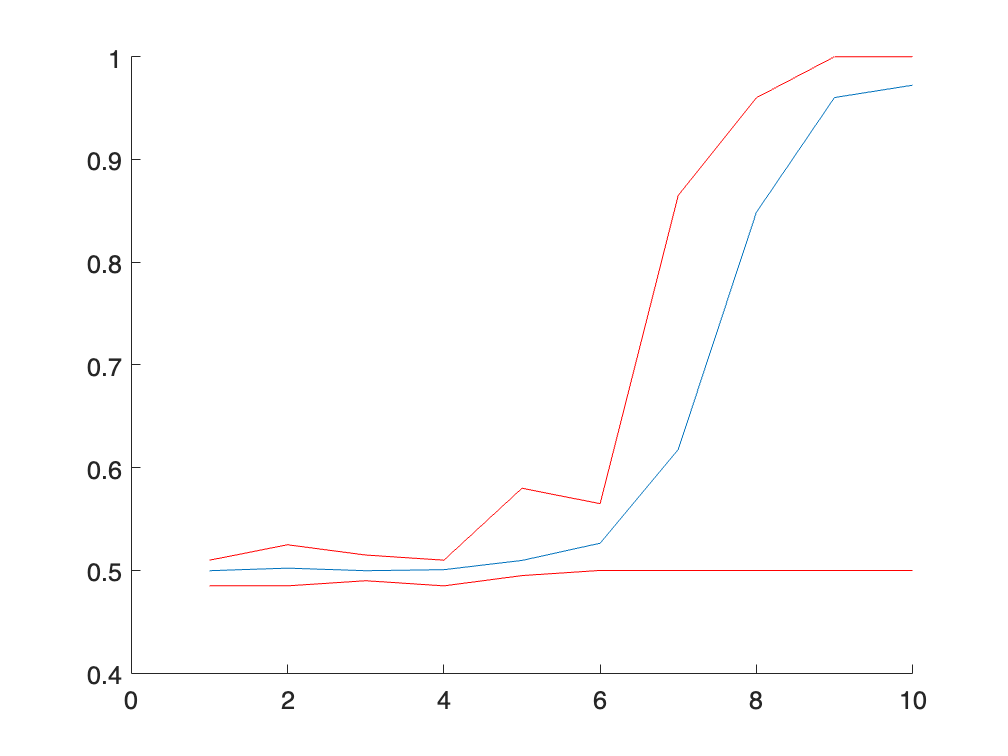

x = [10, 9, 8, 7, 6, 5, 4, 3, 2, 1];                     
y = mean(clustering_acc_mat_sep,1);
y_max = max(clustering_acc_mat_sep);
y_min = min(clustering_acc_mat_sep);
%xconf = [x x(end:-1:1)] ;         
%yconf = [y_max y_min(end:-1:1) ];

figure;
         

hold on
plot(x,y)
plot(x,y_max,'red')
plot(x,y_min,'red')
hold off

p = 6000;
s = p;
n_rep = 20;
sep_vec = linspace(7, 6, 10); %round 2;
mean_full = [ones(p, 1)]';


clustering_acc = repelem(0, length(sep_vec));
clustering_acc_mat_sep_micro = repmat(clustering_acc, n_rep,1);

for j = 1:n_rep
    tic
for i = 1:length(sep_vec)
    sep_now = sep_vec(i);
    M = sqrt(sep_now^2 / 4 / s);
    %data generation
    mu_1 =  -M * mean_full;
    mu_2 =   M * mean_full;
    %norm(mu_1 - mu_2)
    mu_1_mat = repmat(mu_1, n/2,1);
    mu_2_mat = repmat(mu_2, n/2,1);

    x = [ mu_1_mat ; mu_2_mat ] + sigma^2 * randn(n, p);
    A = (x * x')/ n; % original affinity matrix (or similarity matrix)
                    %scaling
    
    % solve SDP problem (implemented in kmeans_sdp.m)
    Z_org = kmeans_sdp(A, K);
    rounded_cluster_one = Z_org>rounding;
    cluster_one_est = find(rounded_cluster_one(:,1));
    rounded_cluster_two = Z_org<rounding;
    cluster_two_est = find(rounded_cluster_two(:,1));
    
    cluster_est = 1:n;
    cluster_est(cluster_one_est) = 1;
    cluster_est(cluster_two_est) = 2;
    clustering_acc_mat_sep_micro(j,i) = mean(cluster_true == cluster_est);
end  
toc
end

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

Elapsed time is 152.707051 seconds.


  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

Elapsed time is 99.133539 seconds.


  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

Elapsed time is 96.955320 seconds.


  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

Elapsed time is 89.507401 seconds.


  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

Elapsed time is 85.301013 seconds.


  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

Elapsed time is 109.604653 seconds.


  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

Elapsed time is 103.312788 seconds.


  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

Elapsed time is 100.279917 seconds.


  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

Elapsed time is 96.913823 seconds.


  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

Elapsed time is 98.342068 seconds.


  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

Elapsed time is 100.571998 seconds.


  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

Elapsed time is 100.136863 seconds.


  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=3.2,  dualfeasorg deteriorated too much: primfeasorg=3.04e-06,dualfeasorg=2.60e-05  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

Elapsed time is 125.983331 seconds.


  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

Elapsed time is 130.261165 seconds.


  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

Elapsed time is 137.338512 seconds.


  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

Elapsed time is 111.368267 seconds.


  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

Elapsed time is 132.434741 seconds.


  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

Elapsed time is 117.850573 seconds.


  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

Elapsed time is 128.656257 seconds.


  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

Elapsed time is 125.810874 seconds.


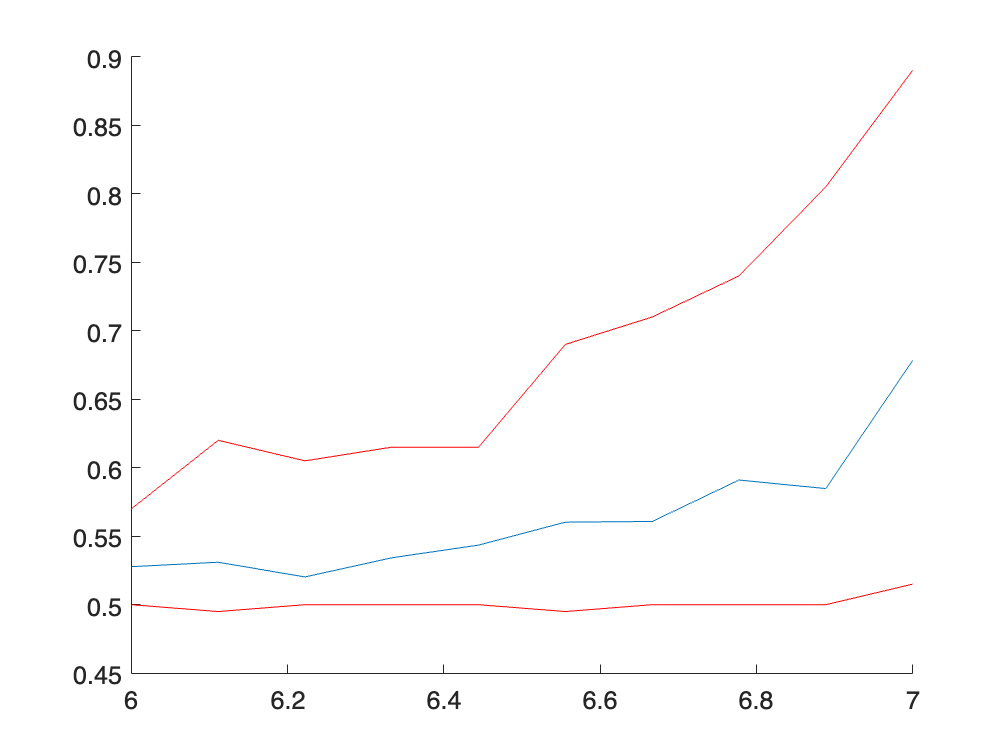

x = sep_vec;                     
y = mean(clustering_acc_mat_sep_micro,1);
y_max = max(clustering_acc_mat_sep_micro);
y_min = min(clustering_acc_mat_sep_micro);


figure;
         

hold on
plot(x,y)
plot(x,y_max,'red')
plot(x,y_min,'red')
hold off

sep = 6.6;
p = 6000;
s_vec = [5000, 4000, 3000, 2000, 1000, 500, 100, 10];
n_rep = 4;
clustering_acc = repelem(0, length(s_vec));
clustering_acc_mat_s = repmat(clustering_acc, n_rep,1);

for j = 1:n_rep
for i = 1:length(s_vec)
    s = s_vec(i)
    M = sqrt(sep^2 / 4 / s)
    
    %data generation
    sparse_mean = [repelem(1,s), repelem(0,p-s)];
    mu_1 =  -M * sparse_mean;
    mu_2 =   M * sparse_mean;
    norm(mu_1 - mu_2)
    mu_1_mat = repmat(mu_1, n/2,1);
    mu_2_mat = repmat(mu_2, n/2,1);

    x = [ mu_1_mat ; mu_2_mat ] + sigma^2 * randn(n, p);
    A = (x * x')/ n; % original affinity matrix (or similarity matrix)
                    %scaling
    
    % solve SDP problem (implemented in kmeans_sdp.m)
    Z_org = kmeans_sdp(A, K);
    rounded_cluster_one = Z_org>rounding;
    cluster_one_est = find(rounded_cluster_one(:,1));
    rounded_cluster_two = Z_org<rounding;
    cluster_two_est = find(rounded_cluster_two(:,1));
    
    cluster_est = 1:n;
    cluster_est(cluster_one_est) = 1;
    cluster_est(cluster_two_est) = 2;
    clustering_acc_mat_s(j, i) = mean(cluster_true == cluster_est);
end  
end

s = 5000

M = 0.0467

ans = 6.6000

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

s = 4000

M = 0.0522

ans = 6.6000

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

s = 3000

M = 0.0602

ans = 6.6000

  breakyes = 1.0,  maxresidual < 1.00e-04

s = 2000

M = 0.0738

ans = 6.6000

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

s = 1000

M = 0.1044

ans = 6.6000

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

s = 500

M = 0.1476

ans = 6.6000

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

s = 100

M = 0.3300

ans = 6.6000

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

s = 10

M = 1.0436

ans = 6.6000

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

s = 5000

M = 0.0467

ans = 6.6000

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

s = 4000

M = 0.0522

ans = 6.6000

  breakyes = 1.0,  maxresidual < 1.00e-04

s = 3000

M = 0.0602

ans = 6.6000

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

s = 2000

M = 0.0738

ans = 6.6000

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

s = 1000

M = 0.1044

ans = 6.6000

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

s = 500

M = 0.1476

ans = 6.6000

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

s = 100

M = 0.3300

ans = 6.6000

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

s = 10

M = 1.0436

ans = 6.6000

  breakyes = 1.0,  maxresidual < 1.00e-04

s = 5000

M = 0.0467

ans = 6.6000

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

s = 4000

M = 0.0522

ans = 6.6000

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

s = 3000

M = 0.0602

ans = 6.6000

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

s = 2000

M = 0.0738

ans = 6.6000

  breakyes = 1.0,  maxresidual < 1.00e-04

s = 1000

M = 0.1044

ans = 6.6000

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

s = 500

M = 0.1476

ans = 6.6000

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

s = 100

M = 0.3300

ans = 6.6000

  breakyes = 1.0,  maxresidual < 1.00e-04

s = 10

M = 1.0436

ans = 6.6000

  breakyes=1.0,  maxresidual < 1.00e-06

s = 5000

M = 0.0467

ans = 6.6000

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

s = 4000

M = 0.0522

ans = 6.6000

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

s = 3000

M = 0.0602

ans = 6.6000

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

s = 2000

M = 0.0738

ans = 6.6000

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

s = 1000

M = 0.1044

ans = 6.6000

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

s = 500

M = 0.1476

ans = 6.6000

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

s = 100

M = 0.3300

ans = 6.6000

  breakyes = 1.0,  maxresidual < 1.00e-04

s = 10

M = 1.0436

ans = 6.6000

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

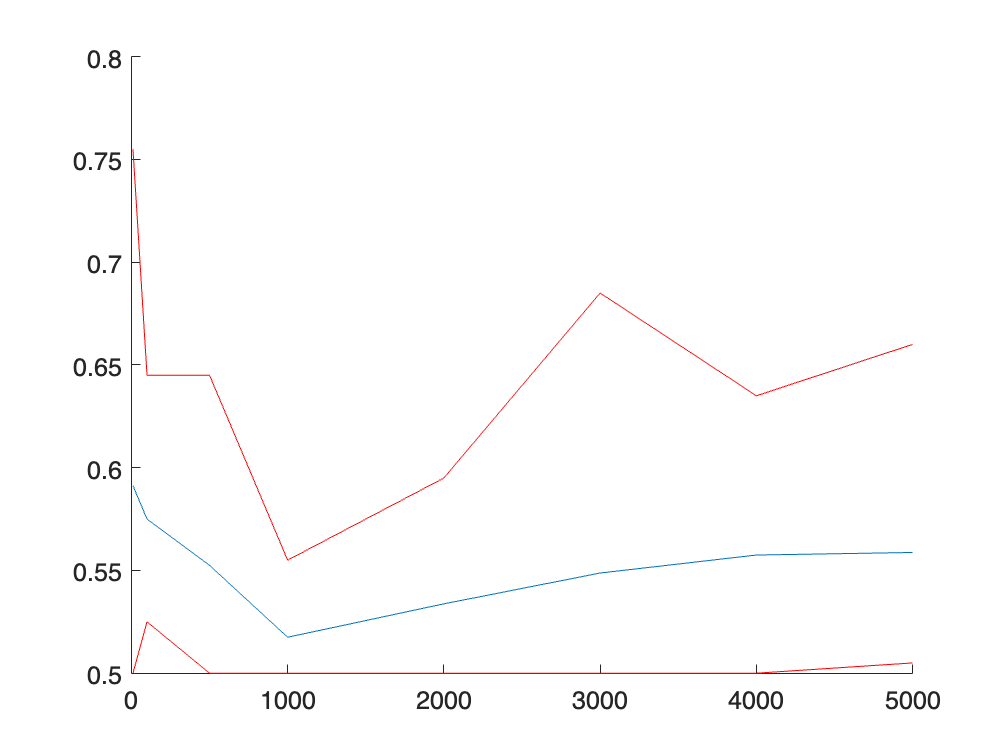

x = s_vec;                     
y = mean(clustering_acc_mat_s,1);
y_max = max(clustering_acc_mat_s);
y_min = min(clustering_acc_mat_s);


figure;
         

hold on
plot(x,y)
plot(x,y_max,'red')
plot(x,y_min,'red')
hold off

sep =7;
s = 10;
p_vec = linspace(10, 5000, 50);
n_rep = 3;
clustering_acc = repelem(0, length(p_vec));
clustering_acc_mat_p = repmat(clustering_acc, n_rep,1);

for j = 1:n_rep
for i = 1:length(p_vec)
    M = sqrt(sep^2 / 4 / s)
    
    %data generation
    sparse_mean = [repelem(1,s), repelem(0,p-s)];
    mu_1 =  -M * sparse_mean;
    mu_2 =   M * sparse_mean;
    norm(mu_1 - mu_2)
    mu_1_mat = repmat(mu_1, n/2,1);
    mu_2_mat = repmat(mu_2, n/2,1);

    x = [ mu_1_mat ; mu_2_mat ] + sigma^2 * randn(n, p);
    A = (x * x')/ n; % original affinity matrix (or similarity matrix)
                    %scaling
    
    % solve SDP problem (implemented in kmeans_sdp.m)
    Z_org = kmeans_sdp(A, K);
    rounded_cluster_one = Z_org>rounding;
    cluster_one_est = find(rounded_cluster_one(:,1));
    rounded_cluster_two = Z_org<rounding;
    cluster_two_est = find(rounded_cluster_two(:,1));
    
    cluster_est = 1:n;
    cluster_est(cluster_one_est) = 1;
    cluster_est(cluster_two_est) = 2;
    clustering_acc_mat_p(j, i) = mean(cluster_true == cluster_est);
end  
end

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04

M = 1.1068

ans = 7

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04

M = 1.1068

ans = 7

M = 1.1068

ans = 7

  breakyes=1.0,  maxresidual < 1.00e-06

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

M = 1.1068

ans = 7

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

M = 1.1068

ans = 7

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

M = 1.1068

ans = 7

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=3.2,  dualfeasorg deteriorated too much: primfeasorg=7.53e-07,dualfeasorg=2.44e-05

M = 1.1068

ans = 7

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

M = 1.1068

ans = 7

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=3.2,  dualfeasorg deteriorated too much: primfeasorg=6.61e-07,dualfeasorg=1.64e-05

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

M = 1.1068

ans = 7

M = 1.1068

ans = 7

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

M = 1.1068

ans = 7

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=3.2,  dualfeasorg deteriorated too much: primfeasorg=1.02e-06,dualfeasorg=3.09e-05

M = 1.1068

ans = 7

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04

M = 1.1068

ans = 7

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04

M = 1.1068

ans = 7

  breakyes = 1.0,  maxresidual < 1.00e-04

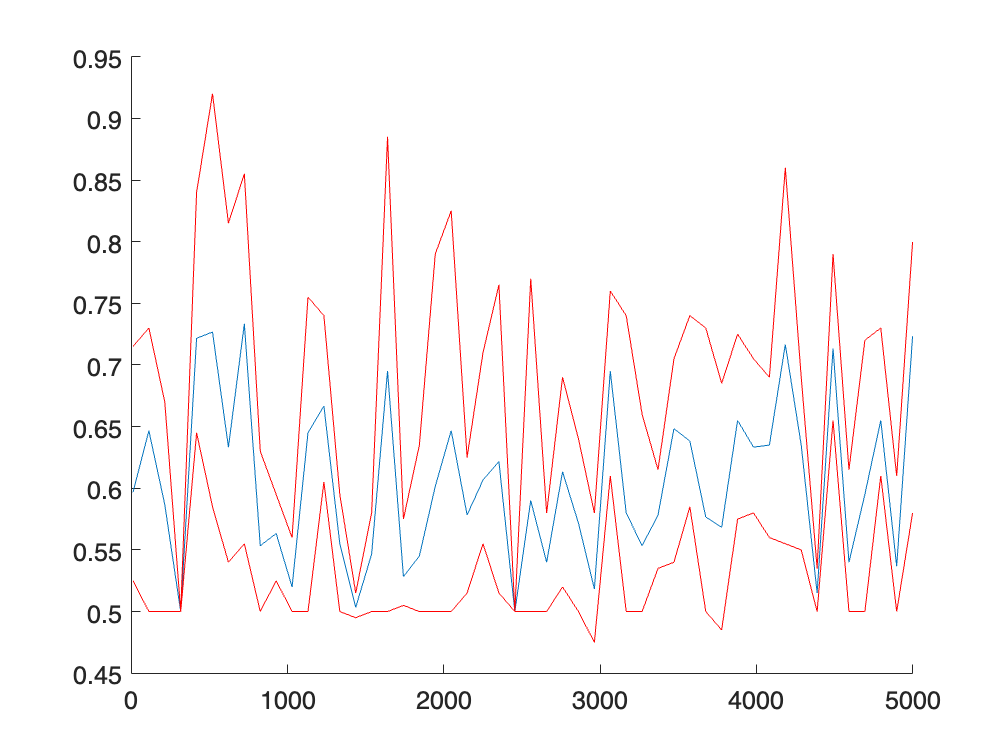

x = p_vec;                     
y = mean(clustering_acc_mat_p,1);
y_max = max(clustering_acc_mat_p);
y_min = min(clustering_acc_mat_p);


figure;
         

hold on
plot(x,y)
plot(x,y_max,'red')
plot(x,y_min,'red')
hold off

when the performance becomes not so good

%p_vec = [4000, 5000, 6000];
%s_vec = [4,4,4]
p = 100;
s = 4;
sep_square = 4 * sigma^2 * ( 1 +  sqrt( 1 + K*s/n/log(n) ) * log(n) );
sep = sqrt((1 + alpha)*sep_square)
sparse_mean = [repelem(1,s), repelem(0,p-s)];
mu_1 =  -sep * sparse_mean;
mu_2 =   sep * sparse_mean;
mu_1_mat = repmat(mu_1, n/2,1);
mu_2_mat = repmat(mu_2, n/2,1);
alpha = 0.1;
n_rep = 1;


clustering_acc = repelem(0,n_rep);

for rep = 1:n_rep                
    %data generation
    x = [ mu_1_mat ; mu_2_mat ] + sigma^2 * randn(n, p);
    A = (x * x'); %/ n; % original affinity matrix (or similarity matrix)
                    %scaling
    
    % solve SDP problem (implemented in kmeans_sdp.m)
    Z_org = kmeans_sdp(A, K);
    rounded = Z_org>rounding;
    cluster_est = find(rounded(:,1));
    clustering_acc(rep) = mean(cluster_true' == cluster_est);
end  

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

Z_org

Z_org =     0.0103    0.0100    0.0099    0.0100    0.0103    0.0099    0.0101    0.0100    0.0101    0.0101    0.0099    0.0102    0.0102    0.0102    0.0103    0.0100    0.0104    0.0098    0.0101    0.0100    0.0101    0.0102    0.0099    0.0102    0.0099    0.0100    0.0100    0.0101    0.0098    0.0104    0.0098    0.0102    0.0099    0.0100    0.0101    0.0100    0.0102    0.0100    0.0103    0.0102    0.0099    0.0099    0.0100    0.0100    0.0103    0.0099    0.0101    0.0101    0.0100    0.0100
    0.0100    0.0101    0.0101    0.0101    0.0100    0.0101    0.0101    0.0101    0.0101    0.0100    0.0101    0.0100    0.0100    0.0100    0.0100    0.0101    0.0100    0.0102    0.0101    0.0101    0.0100    0.0100    0.0101    0.0100    0.0101    0.0101    0.0101    0.0100    0.0102    0.0099    0.0102    0.0100    0.0101    0.0101    0.0100    0.0101    0.0100    0.0101    0.0100    0.0100    0.0101    0.0101    0.0101    0.0101    0.0100    0.0101    0.0101    0.0101    0.0101 

clustering_acc

clustering_acc =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.5050    0.5050


rounded

rounded = 200×200 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1

% disadvangage of their bound. dependence on p is p 
%a = 0.1;



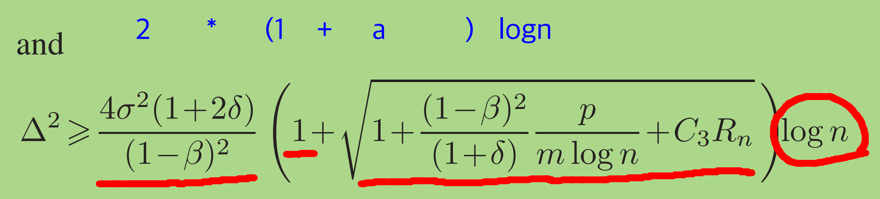\

**how to determine a?**

\

(p=1 i.e. univariate gaussian)

### Original method vs thresholding

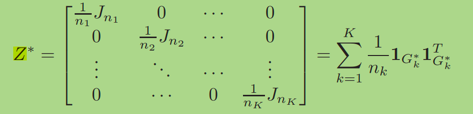



% takes about 15 seconds on this laptop


figure;

A =    20.2874   20.2980   20.4285   20.4702   19.4013   20.8367   20.2299   19.9411   20.2810   20.6136   20.3596   20.8405   20.4206   20.1139   20.2824   20.7341   20.6394   20.2838   20.7089   20.0325   21.2540   20.1800   20.6597   20.1835   20.1331   21.1927   20.0354   20.9295   21.2046   20.3608   20.3059   20.4310   21.3180   20.0476   20.6977   20.1218   20.3876   20.2708   19.8016   19.9234   20.8896   20.6627   21.1059   20.5182   20.5579   19.8970   20.5678   20.2358   20.2384   20.0546
   20.2980   20.4027   20.4809   20.5475   19.4922   20.8947   20.2664   19.9924   20.3319   20.6399   20.4199   20.8819   20.4934   20.1579   20.3061   20.7710   20.6768   20.2846   20.7664   20.0545   21.3120   20.2024   20.7028   20.2545   20.1845   21.2424   20.1227   20.9553   21.2384   20.3892   20.3315   20.4957   21.3557   20.0845   20.7606   20.1115   20.4519   20.3007   19.8793   20.0064   20.9351   20.6982   21.0969   20.5886   20.5937   19.9548   20.5685   20.2781   20.3327   20

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06


subplot(2,2,1)
imagesc(Z_org)
title('SDP solution (original)')
colormap('winter')
colorbar
colormap(flipud(colormap));
set(gca,'xtick',[])
set(gca,'ytick',[])
axis equal
a=axis;
a(1)=a(3);
a(2)=a(4);
axis(a)
%
subplot(2,2,2)
imagesc(A)
title('Affinity matrix (original)')
colormap('winter')
colorbar
colormap(flipud(colormap));
set(gca,'xtick',[])
set(gca,'ytick',[])
axis equal
a=axis;
a(1)=a(3);
a(2)=a(4);
axis(a)
%
subplot(2,2,3)
imagesc(Z_thres)
title('SDP solution (thresholded)')
colormap('winter')
colorbar
colormap(flipud(colormap));
set(gca,'xtick',[])
set(gca,'ytick',[])
axis equal
a=axis;
a(1)=a(3);
a(2)=a(4);
axis(a)
%
subplot(2,2,4)
%imagesc(abs(A))
imagesc(A_thres)
title('Affinity matrix (thresholded)')
colormap('winter')
colorbar
colormap(flipud(colormap));
set(gca,'xtick',[])
set(gca,'ytick',[])
axis equal
a=axis;
a(1)=a(3);
a(2)=a(4);
axis(a)

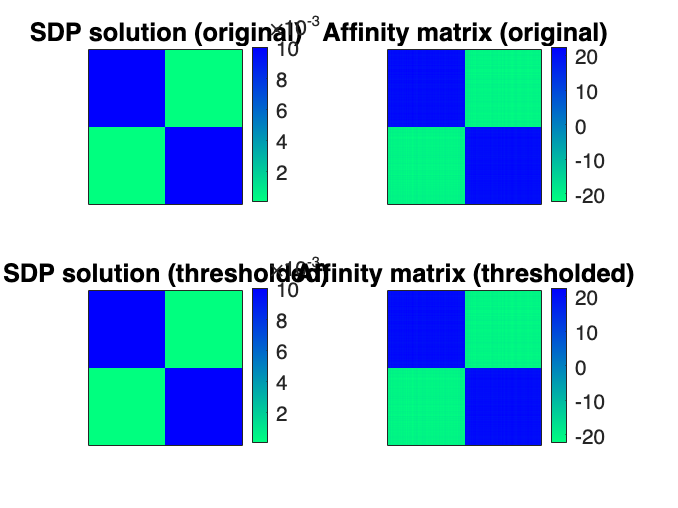

ans =    -7.3146         0  -15.4388  -13.2934  -10.6362   -8.0561         0   -9.9084         0         0         0   -7.9760  -11.6088  -15.4308   -7.8437         0   -9.9206  -11.0710   -9.9950  -13.6472  -10.8495   -9.4021   -8.3519   -8.8600         0   -8.0577         0   -7.1181         0  -11.9161         0   -9.7707         0         0  -18.6968  -14.7153  -15.2436         0         0  -10.0792         0         0  -13.4388         0  -12.0495         0   -8.7153         0  -10.5346         0



min(A.*(abs(A)>thres))

